# Simulazione Veicolo Autobilanciato - gruppo Calegari

## Setup iniziale dell'ambiente

clear
clc
digits(4)

%load('WS_VAB_wb_0.mat','A','B','C','D','r');
load('WS_VAB_wb_0_5.mat','A','B','C','D','r');


## Analisi stabilità

Studio dell'asintotica stabilità tramite gli autovalori della matrice A: come noto dalla teoria, il sistema è asintoticamente stabile se gli autovalori hanno tutti parte reale negativa; è instabile invece se è presente almeno un autovalore con parte reale strettamente positiva.

% Passing from symbolic to real values
A_real = double(A);
B_real = double(B);
C_real = double(C);
D_real = double(D);

sys = ss(A_real,B_real,C_real,D_real) % Same of G


sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -16.19       0
   x3       0       0       0       1
   x4       0       0   5.129       0
 
  B = 
             u1
   x1         0
   x2    0.2895
   x3         0
   x4  -0.02968
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



lambda = eig(A_real)

lambda =          0
         0
    2.2648
   -2.2648


Come si vede il sistema non è asintoticamente per la presenza di autovalori con parte reale non strettamente positiva.

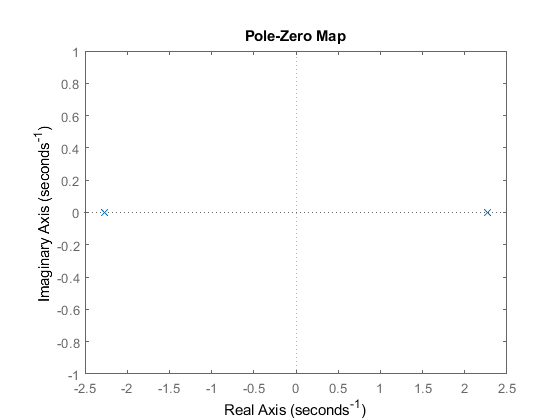

pzplot(sys)

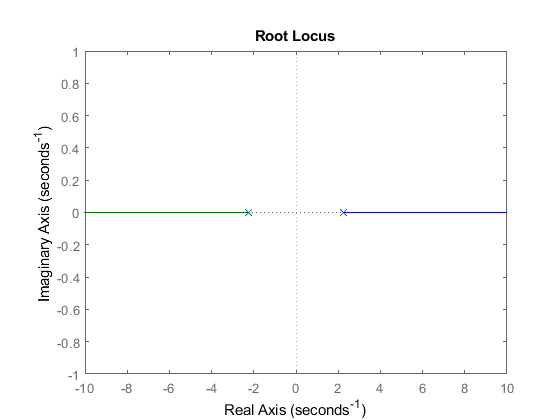

rlocus(sys)

M_r = ctrb(sys) % Matrice di raggiungibilità

M_r =          0    0.2895         0    0.4804
    0.2895         0    0.4804         0
         0   -0.0297         0   -0.1522
   -0.0297         0   -0.1522         0


rank(M_r)

ans = 4

M_o = obsv(sys) % Matrice di osservabilità

M_o =          0         0    1.0000         0
         0         0         0    1.0000
         0         0    5.1293         0
         0         0         0    5.1293


rank(M_o)

ans = 2


K0 = dggain(sys)
zero(sys)
pole(sys)
damp(sys)

Si vede come il sistema, in anello aperto, non sia asintoticamente stabile (come previsto), dalle analisi sugli autovalori e sui poli.

Lo stato del sistema, nel nostro caso, risulta essere accessibile, poichè sono misurazioni che possono essere direttamente realizzate per mezzo di tecniche di sensor fusion.

Per ora vogliamo controllare solamente l'angolo $\theta \;$, e quindi ci poniamo in una condizione di sistema SISO (input la coppia motrice, output l'accelerazione $\ddot{\theta \;}$):


$${\left\{\begin{array}{c}
x\left(t\right)=Ax{\left(t\right)}+Bu\left(t\right)\\
y{\left(t\right)}=Cx{\left(t\right)}+Du\left(t\right)
\end{array}\right)}$$


Utilizzando la legge di controllo


$$u{\left(t\right)}=-Kx{\left(t\right)}+w{\left(t\right)}$$


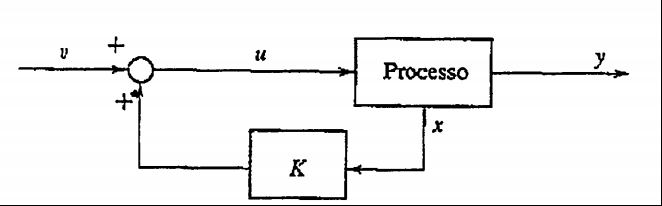

Per la scelta della matrice K


$$x{\left(t\right)}=Ax{\left(t\right)}+Bu{\left(t\right)}=Ax{\left(t\right)}+B{\left(-Kx{\left(t\right)}+w{\left(t\right)}\right)}\to legge\ di\ controllo\ in\ anello\ chiuso$$



$$=Ax{\left(t\right)}-BKx{\left(t\right)}+Bw\left(t\right)={\left(A-BK\right)}x{\left(t\right)}+Bw{\left(t\right)}$$



$$A_{cl} =A-BK=matrice\;di\;stato\;in\;closed-loop$$


## Posizionamento dei poli

Per andare a calcolare questo vettore dei poli K, possiamo utilizzare il comando ***place***.

Per fare ciò ci atteniamo ai parametri richiesti per entrambi i poli, ovvero:

- Smorzamento $=\xi =0\ldotp 7$

- Pulsazione naturale polo $=\omega {\;}_{n\;} =2\bullet \pi \bullet f_{\textrm{propria}}$

In generale sappiamo che


$$G{\left(S\right)}=\frac{1}{s^2 +2\xi \omega {\;}_n s+\omega {\;}_n^{2\;} }=\frac{1}{1+2∙\frac{\textrm{𝜉}}{{\textrm{𝜔}}_n }s+\frac{s^2 }{{\textrm{𝜔}}_n^2 }}$$


Per trovare i poli mi basta risolvere l'equazione al denominatore, trovando i valori di s che l'annullano:

syms xsi wn1 wn2 s;
% Definisco le funzioni di trasferimento
dd_1 = s^2 + s * 2 * xsi * wn1 + wn1^2 == 0;
dd_2 = s^2 + s * 2 * xsi * wn2 + wn2^2 == 0;
sol_dd_1 = solve(dd_1, s);
sol_dd_2 = solve(dd_2, s);

Definisco la pulsazione naturale per primo polo, destinato al controllo più veloce per l'angolo $\theta \;\ldotp$

% fn1 = 20; % [Hz]
fn1 = 0.1; % [Hz]
w1 = 2*pi*fn1; % [rad / s]

Definisco i parametri anche per il secondo polo, invece più lento e destinato a $\phi \;\ldotp$

% fn2 = 2; % [Hz]
fn2 = 0.01; % [Hz]
w2 = 2*pi*fn2; % [rad / s]

Definisco anche lo smorzamento per i poli (

e =0.7; % Smorzamento

Sostituisco i parametri numeri di pulsazione e smorzamento nelle soluzione dei poli:

pol_1 = subs(sol_dd_1,{xsi,wn1},{e,w1});
pol_2 = subs(sol_dd_2,{xsi,wn2},{e,w2});
pol_1_real = double(pol_1)

pol_1_real =   -0.4398 + 0.4487i
  -0.4398 - 0.4487i


pol_2_real = double(pol_2)

pol_2_real =   -0.0440 + 0.0449i
  -0.0440 - 0.0449i


K = place(A_real,B_real,[pol_1_real', pol_2_real'])

K =    -0.0016   -0.0380 -188.9062  -32.9772


save('K.mat','K');

Calcolo la nuova matrice A in anello chiuso con i valori di K:

A_cl = A_real-B_real * K;

Verifico che i nuovi autovalori abbiano parte reale negativa.

eigenvalues = eig(A_cl)

eigenvalues =   -0.4398 + 0.4487i
  -0.4398 - 0.4487i
  -0.0440 + 0.0449i
  -0.0440 - 0.0449i


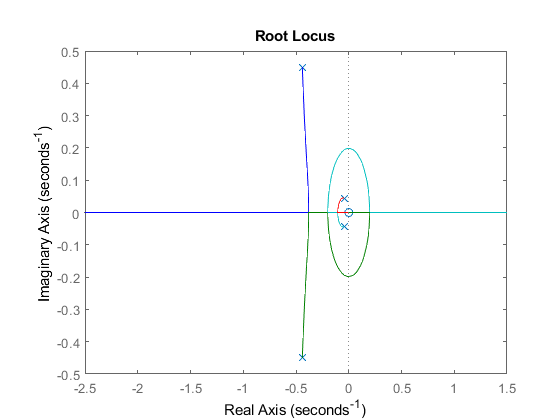

sys_cl = ss(A_cl,B_real,C_real,D_real);
rlocus(sys_cl)

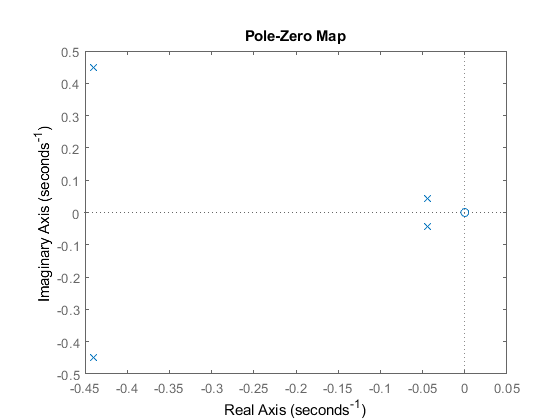

pzmap(sys_cl)

Posso utilizzare un'altra tecnica per realizzare il place dei poli (LQR - Regolatore Lineare Quadratico) che rappresenta una soluzione ottima per il pole placement:

Q = eye(4);
R = 1;
K_lqr = lqr(A_real,B_real,Q,R)

K_lqr =    -1.0000   -4.2629 -463.4920 -216.7324


K = K_lqr

K =    -1.0000   -4.2629 -463.4920 -216.7324


## Simulazione

### Condizioni iniziali

% Initial condition for open loop model
x_0 = [0; 0; 5 * pi / 180; 0];
phi_iniziale = x_0(1);
phi_p_iniziale = x_0(2);
theta_iniziale = x_0(3);
theta_p_iniziale = x_0(4);
r_simulazione = double(r)

r_simulazione = 0.2200

control_on = 0;
t_end = 5;
Ts = 1/100;
%vale solo nel non lineare alpha
alpha_simulazione = double(0);
disp('Open loop');

Open loop


## Sistema in anello aperto

### Sistema Lineare

disp('Linear system');

Linear system


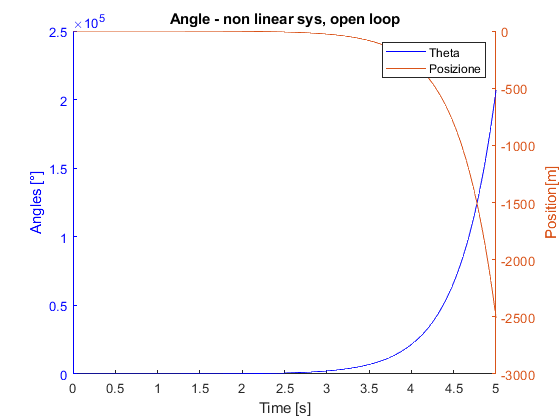

simOut = sim('VAB_Linear_PolePlacement');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - non linear sys, open loop')

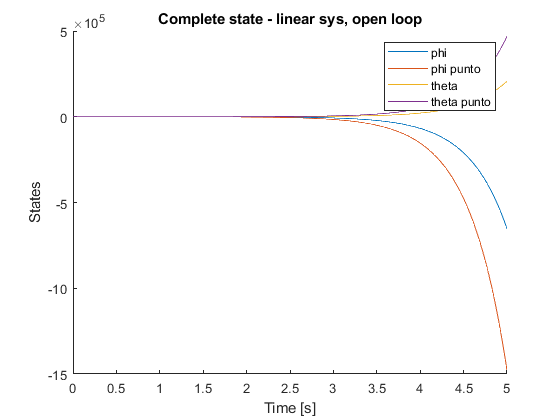



figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - linear sys, open loop')
legend('phi', 'phi punto', 'theta', 'theta punto');


% for i=1:size(completeState,1)
%     call_plot(completeState(i,:))
% end

### Sistema non lineare

disp('Non linear system');

Non linear system


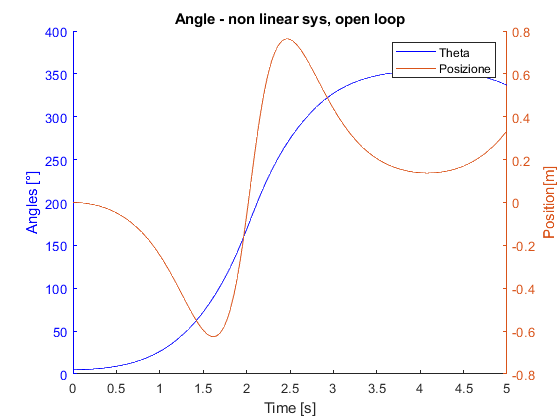

simOut = sim('VAB_non_linear.slx');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - non linear sys, open loop')

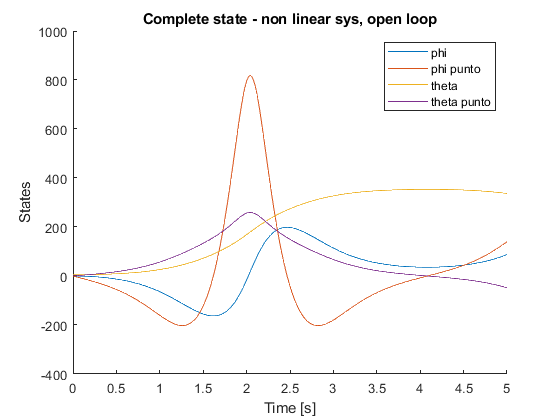


figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - non linear sys, open loop')
legend('phi', 'phi punto', 'theta', 'theta punto');

## Simulazione con controllo

### Sistema lineare

disp('Closed loop');

Closed loop


disp('Linear system');

Linear system


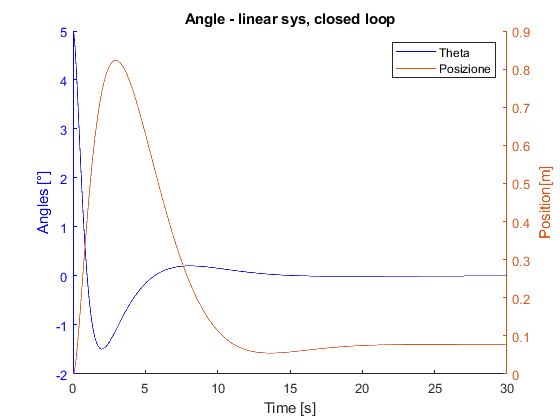

control_on = 1;
t_end = 30;
Ts = 1/100;

simOut = sim('VAB_Linear_PolePlacement');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - linear sys, closed loop')

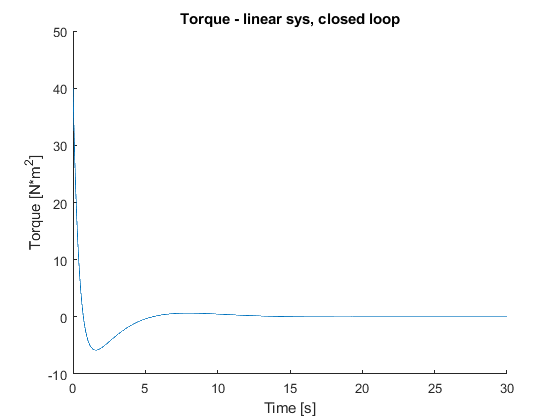


figure
hold on
plot(tout, torque)
xlabel('Time [s]')
ylabel('Torque [N*m]')
title('Torque - linear sys, closed loop')

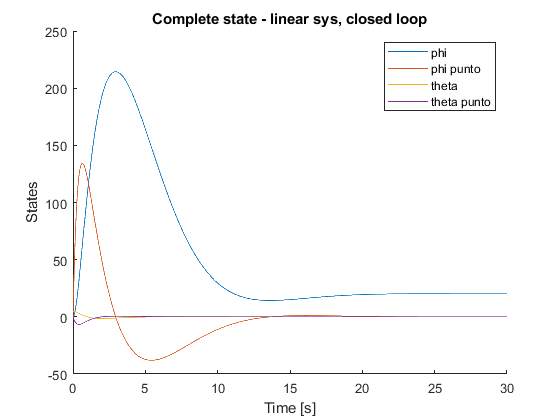


figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - linear sys, closed loop')
legend('phi', 'phi punto', 'theta', 'theta punto');


% for i=1:size(completeState,1)
%     call_plot(completeState(i,:))
% end

### Sistema non lineare

disp('Non linear system');

Non linear system


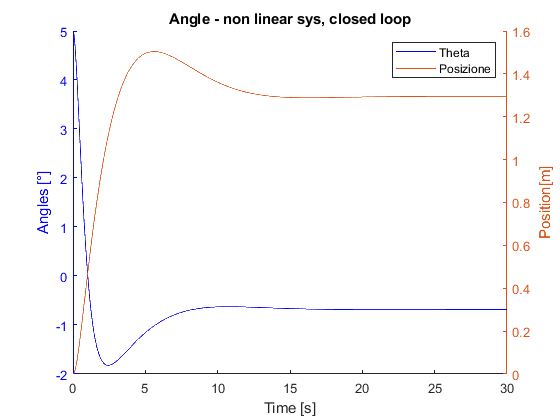

control_on = 1;
simOut = sim('VAB_non_linear.slx');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - non linear sys, closed loop')

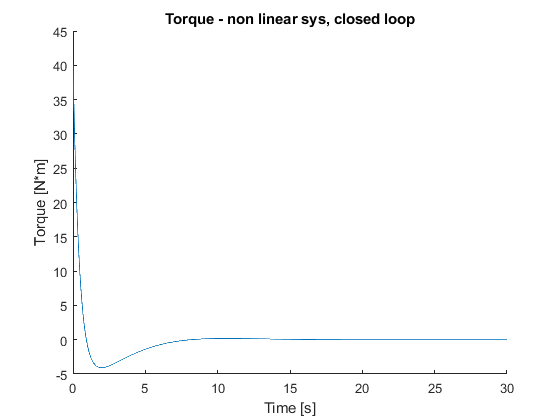



figure
hold on
plot(tout, torque)
xlabel('Time [s]')
ylabel('Torque [N*m]')
title('Torque - non linear sys, closed loop')

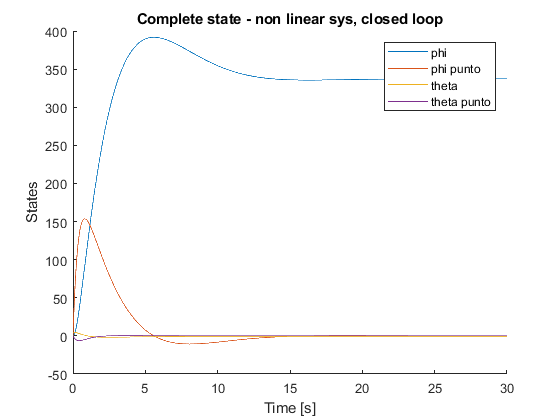


figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - non linear sys, closed loop')
legend('phi', 'phi punto', 'theta', 'theta punto');

NB: State needs to be defined in rad!

call_plot(completeState * pi / 180);